## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

**Example 02 Deployment of Scissor Mechanism**

The previous example is just a truss system, which is not particularly interesting because the deformation is too small. Here, let's see a case of the scissor mechanism to see how the simulation can handle the large deformation and the kinematics of these mechanisms. The following figure defines the geometry and design of the scissor mechanism we hope to model. 

 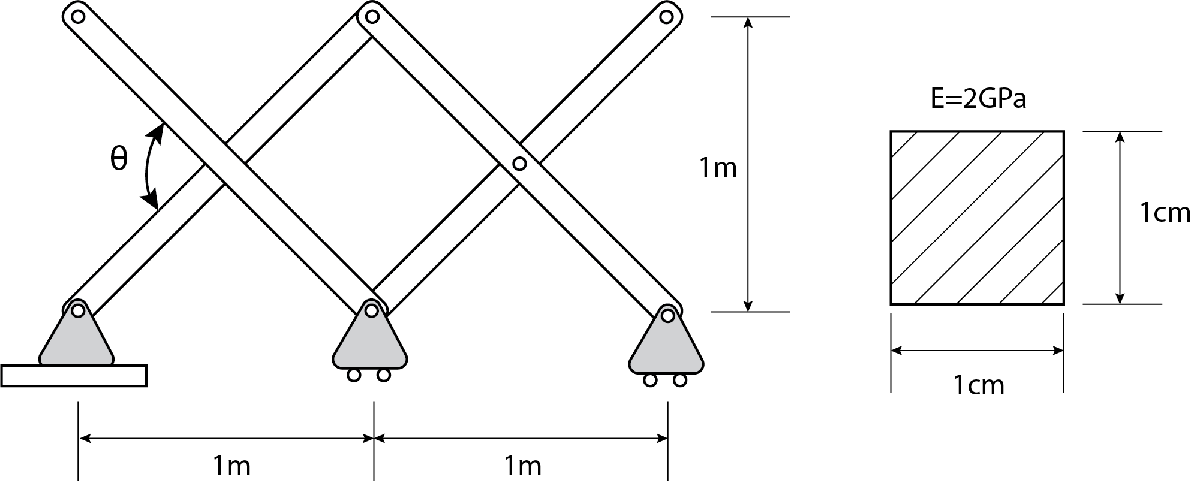

At the resting configuration, each bay is 1 meter and the hieght of the system is also 1 meter. Thus, each rod member in the scissor is 1.414 meter long. The $\theta \;$angle is used to controle the deplyoment process of this scissor mechanism. 

To start using the code, we first clear unwanted storage and plot windows using the following command. 

clear all;
clc;
close all;

Next, we try to innitialize the model and define basic variables we will use. Here, we will need the height of the scissor mechanism $H=1m$; the length of each bay $L=1m$ at at-rest configuration; The area of the truss elements $\textrm{barA}=0\ldotp 0001m^{2\;} ;$ and finally, the Young's modulus of the rod member $\textrm{barE}=2\times {10}^{9\;} \textrm{Pa}$. Please noet that these parameters are on the softer side and we will neglect the buckling of these rod. 

%% Initialize the truss
% Define the nodes
H=1; % Height of the truss
L=1; % Length of each span
barA=0.0001; % cross section area (m^2)
barE=2*10^9; % Youngs' modulus (Pa)

We will use the pseudo-rigid-body model coined by Larry Howell in his textbook "Compliant Mechanism" to consider the bending stiffness of each rod. This concept is illustrated in the following figure, where the bending of the rod is represented with lumped rotational springs $k_{\textrm{spr}}$. 

For a design like this, the rotational spring stiffness is calculated as:


$$k_{\textrm{spr}} =3\frac{\textrm{EI}}{\;L}$$


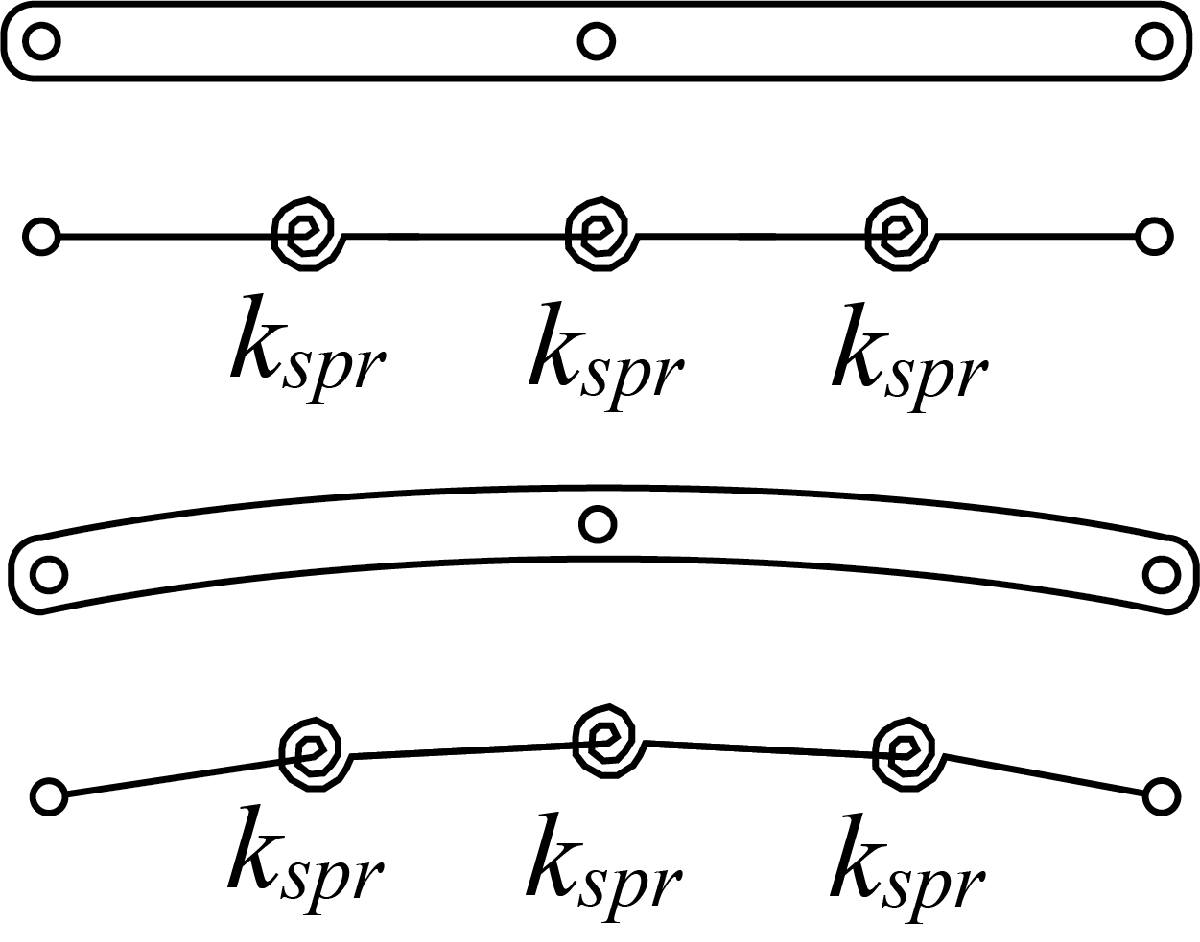

% We will also solve for the bending stiffness of the frame
I=1/12*0.01^4;
% When using four segment to represent a frame, 
% three rotational springs are used
% Using Larry Howell's pseudo rigid body model
% We can convert the bending stiffness to spring stiffness
barL=sqrt(H^2+L^2);
kspr=3*barE*I/barL;

Next we create the node object and bar object based on the class "Elements_Nodes" and "CD_Elements_Bars" just like what we did in Example 01. In addition to the two object, this model will need a three node rotational spring element from "CD_Elements_RotSprings_3N".

% Define the node object
node=Elements_Nodes;
% Create the bar object
bar=CD_Elements_Bars;
% Create the 3-node rot spring
rot_spr_3N=CD_Elements_RotSprings_3N;

After setting up the objects, we can create the assembly for the 2D mechanism, which is also an object. This assembly class is created to help with the ploting and solver operation. The process is just like what we did in Example 01.

% Create tje truss Assembly
assembly=Assembly_2D_Mechanism;
% This assembly has a node object and a bar object
assembly.node=node;
assembly.bar=bar;
assembly.rot_spr_3N=rot_spr_3N;

After seting up the assembly, we will define the nodal coordinates. Here, a total of 16 node is needed and they are stored in the matrix "coordinates_mat" in the node object. 

%% Define the nodal coordinates
% Here we need to set up the nodal coordinates of our truss
node.coordinates_mat=[0*L 0 0; 
                      1*L 0 0;
                      2*L 0 0; % Node 3
                      0*L 0 H;
                      1*L 0 H; 
                      2*L 0 H; % Node 6
                      0.5*L 0 0.5*H; 
                      1.5*L 0 0.5*H; % Node 8
                      0.25*L 0 0.25*H;
                      0.75*L 0 0.25*H;
                      1.25*L 0 0.25*H;
                      1.75*L 0 0.25*H; % Node 12
                      0.25*L 0 0.75*H;
                      0.75*L 0 0.75*H;
                      1.25*L 0 0.75*H;
                      1.75*L 0 0.75*H; % Node 16
                      ];

Here the nodes are located in the XZ plane. This is why the second column (Y-axis) is all zero. Now, to check if we entered the correct nodal coordinates or not, we plot the nodes. 

% Set up the plotting function for inspection
plots=Plot_2D_Mechanism();
plots.assembly=assembly;
% We will plot for the 2D mechnism assembly

Before plotting, we set a couple variable for the plotting function. This include the range we want to plot and the angles we hope to look into the object. Here, 0 for the viewAngle1 and viewAngle2 will give us the XZ plane. We next plot the place of this node. 

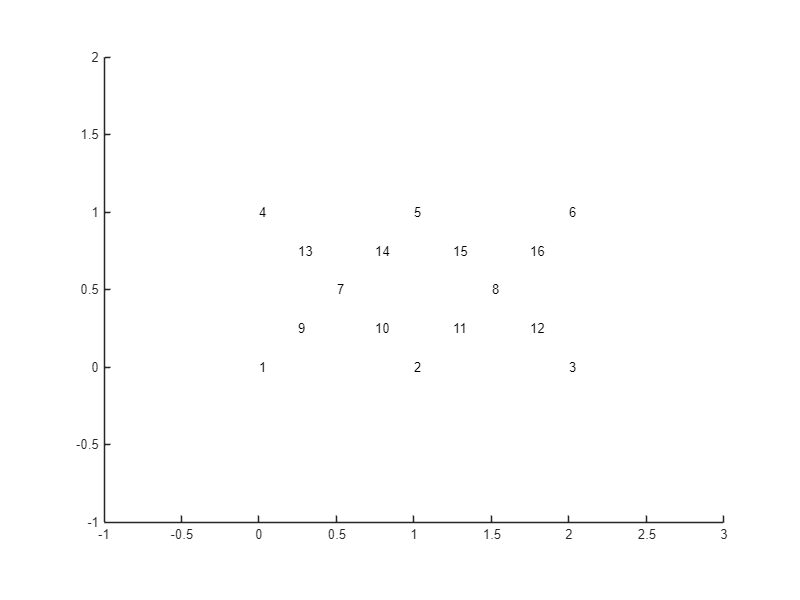

plots.displayRange=[-1;3;-1;1;-1;2]; 
% Range of the plot
plots.viewAngle1=0;
plots.viewAngle2=0;
% Change the viewing angle

plots.Plot_Shape_Node_Number()

% Plot the nodal coordinates for inspection

Looking good! We have two cross and the nodes are at the right place.

Now that have the nodes defined, we can further define the bar elements for the rods in the scissor mechanism. Here we need to add rows to the matrix "node_ij_mat" in the bar object. Each row of the matrix gives the two node of one bar. 

% Define how bars are connected
% First we do the horizontal truss (bars)
bar.node_ij_mat=[1,9;
                 7,9;
                 7,14;
                 14,5; % 4 bars
                 4,13;
                 13,7;
                 7,10;
                 10,2; % 8 bars
                 2,11;
                 11,8;
                 8,16;
                 16,6; % 12 bars
                 5,15;
                 15,8;
                 8,12;
                 12,3;]; % 16 bars

After setting how how bars are connected, we will continue to define the properties of the bar element - the area of each truss and the Young's modulus of each truss. This is done with the following code.

% Define the area of the bars
% We have a total of 16 bars
bar.A_vec=barA*ones(16,1);
bar.E_vec=barE*ones(16,1);

Let's first plot the bar elements to see if everything looks good. 

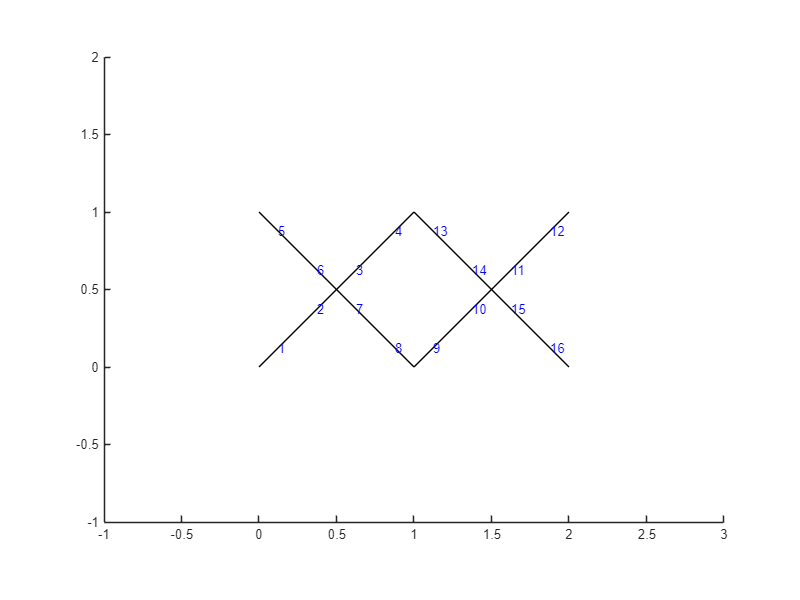

% Initialize the entire assembly 
assembly.Initialize_Assembly();
% Set up the 
plots.Plot_Shape_Bar_Number()

 It looks like everything is working perfectly!

Here, we want to add the 3-node rotational spring. This 3-node rotational spring is defined using the three node - node-i, node-j, and node-k. The connectivity information is stored in the following "node_ijk_mat". 

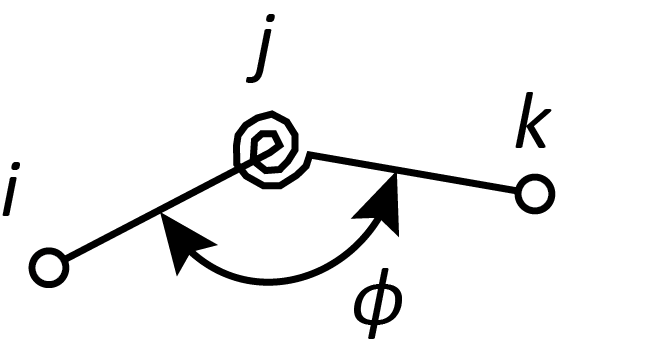

% Define how rotational springs are connected
rot_spr_3N.node_ijk_mat=[1 9 7;
                         9 7 14;
                         7 14 5; % 3 springs
                         4 13 7; 
                         13 7 10; 
                         7 10 2; % 6 springs
                         2 11 8; 
                         11 8 16; 
                         8 16 6; % 9 springs
                         5 15 8;  
                         15 8 12; 
                         8 12 3;]; % 12 springs

In addition to the above 12 basic rotational springs used to capture the bending of the scissor mechanism. We add a 13th rotational spring (connecting node 9-7-13) to control the deployment (the $\theta \;$angle).

% We add another #13 spring to control the deployment
rot_spr_3N.node_ijk_mat=[rot_spr_3N.node_ijk_mat;
                         9 7 13];

Then, we define the rotational spring stiffness of all the rotational springs, reinitialize the assembly and plot the numbering of the spring. 

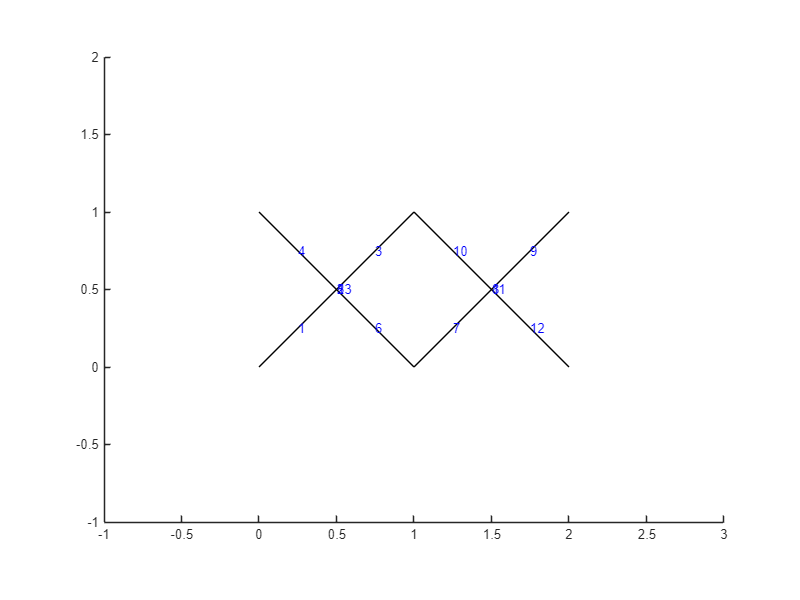

% Define rotational stiffness
rot_spr_3N.rot_spr_K_vec=kspr*ones(13,1);
% Initialize the entire assembly again for the new rot-spring
assembly.Initialize_Assembly();
% Plot the rotational spring number
plots.Plot_Shape_Spr_Number

It looks like we have all the springs set up perfectly!

We can now define the deployment simulation. We will set up a Newton-Raphson solver to solve for the responses in the structure. "nr" is the object created based on the solver class "Solver_NR_Folding_3N". 

Again, each row in the "supp" matrix represents one support. The first column is used to represent the node number while the remaining three columns are used to represent if XYZ deformation is restricted or not (1 means support provided, 0 means free to move). Because this is a 2D problem, the Y-axis deformation is all restricted. The support is set up based on the first figure.

%% Set up the loading solver
nr=Solver_NR_Folding_3N;
nr.assembly=assembly;
nr.supp=[1,1,1,1;
         2,0,1,1;
         3,0,1,1;
         4,0,1,0;
         5,0,1,0;
         6,0,1,0;
         7,0,1,0;
         8,0,1,0;
         9,0,1,0;
         10,0,1,0;
         11,0,1,0;
         12,0,1,0;
         13,0,1,0;
         14,0,1,0;
         15,0,1,0;
         16,0,1,0;];

Next, we will set up deployment. We want to fold the $\theta \;$angle to 0.9$\pi \ldotp$ Thus, we set the target rotation angle, "target rot", as the following. First, the "target rot" is set to be the current theta angle "theta_current_vec". Next, we set the 13th target rotation to be 0.9$\pi \ldotp \;$

% Set up the load
nr.target_rot=rot_spr_3N.theta_current_vec;
nr.target_rot(13)=pi*0.9;

We will compute the deployment in 80-steps. Each step, we allow a maximum of 30 iterations to find the equilibrium using the Newton's method.

% Set up the total loading step
nr.increStep=80;
% Set up the maximum iteration
nr.iterMax=30;
% Set up the tolorence
nr.tol=10^-6;

Now that everything is creatd, we can ask the program to find the deployment history Uhis for us. This is done by asking the solver object "nr" to perform the "Solve()" function. 

% Solve for the deformation history
Uhis=nr.Solve();

Self Assemble Analysis StartIcrement = 1
	Iteration = 1, R = 3.141585e-01 
	Iteration = 2, R = 1.338452e+01 
	Iteration = 3, R = 2.715105e-04 
	Iteration = 4, R = 1.752005e-03 
	Iteration = 5, R = 1.777851e-07 
Icrement = 2
	Iteration = 1, R = 3.153905e-01 
	Iteration = 2, R = 1.346397e+01 
	Iteration = 3, R = 1.789069e-04 
	Iteration = 4, R = 2.764897e-03 
	Iteration = 5, R = 3.252032e-07 
Icrement = 3
	Iteration = 1, R = 3.166167e-01 
	Iteration = 2, R = 1.349956e+01 
	Iteration = 3, R = 3.873054e-04 
	Iteration = 4, R = 2.556055e-03 
	Iteration = 5, R = 1.947120e-07 
Icrement = 4
	Iteration = 1, R = 3.178375e-01 
	Iteration = 2, R = 1.348946e+01 
	Iteration = 3, R = 2.458475e-04 
	Iteration = 4, R = 1.943519e-03 
	Iteration = 5, R = 2.454054e-07 
Icrement = 5
	Iteration = 1, R = 3.190527e-01 
	Iteration = 2, R = 1.355304e+01 
	Iteration = 3, R = 2.179980e-04 
	Iteration = 4, R = 2.676801e-03 
	Iteration = 5, R = 2.766058e-07 
Icrement = 6
	Iteration = 1, R = 3.202622e-01 
	Iteration

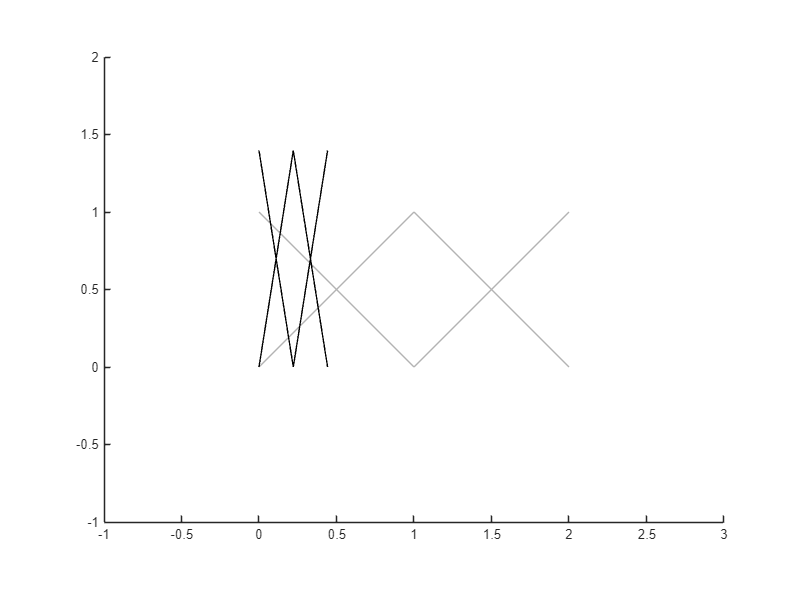

% Plot the deformed shape
plots.Plot_Deformed_Shape(squeeze(Uhis(end,:,:)));

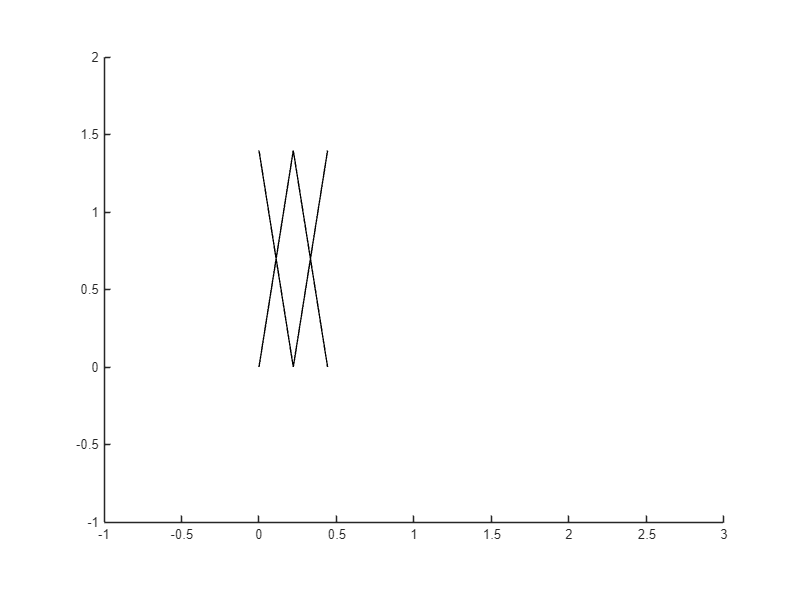

% Also plot the deformation history
plots.fileName="Scissor_Mechanism_Deploy.gif";
plots.Plot_Deformed_His(Uhis);

After finding the deformation, we can further ask the software program to create an animation for the deployment. This is done using the "Plot_Deformed_His" function. Now open the GIF animation and see if this is what we hope to get! 

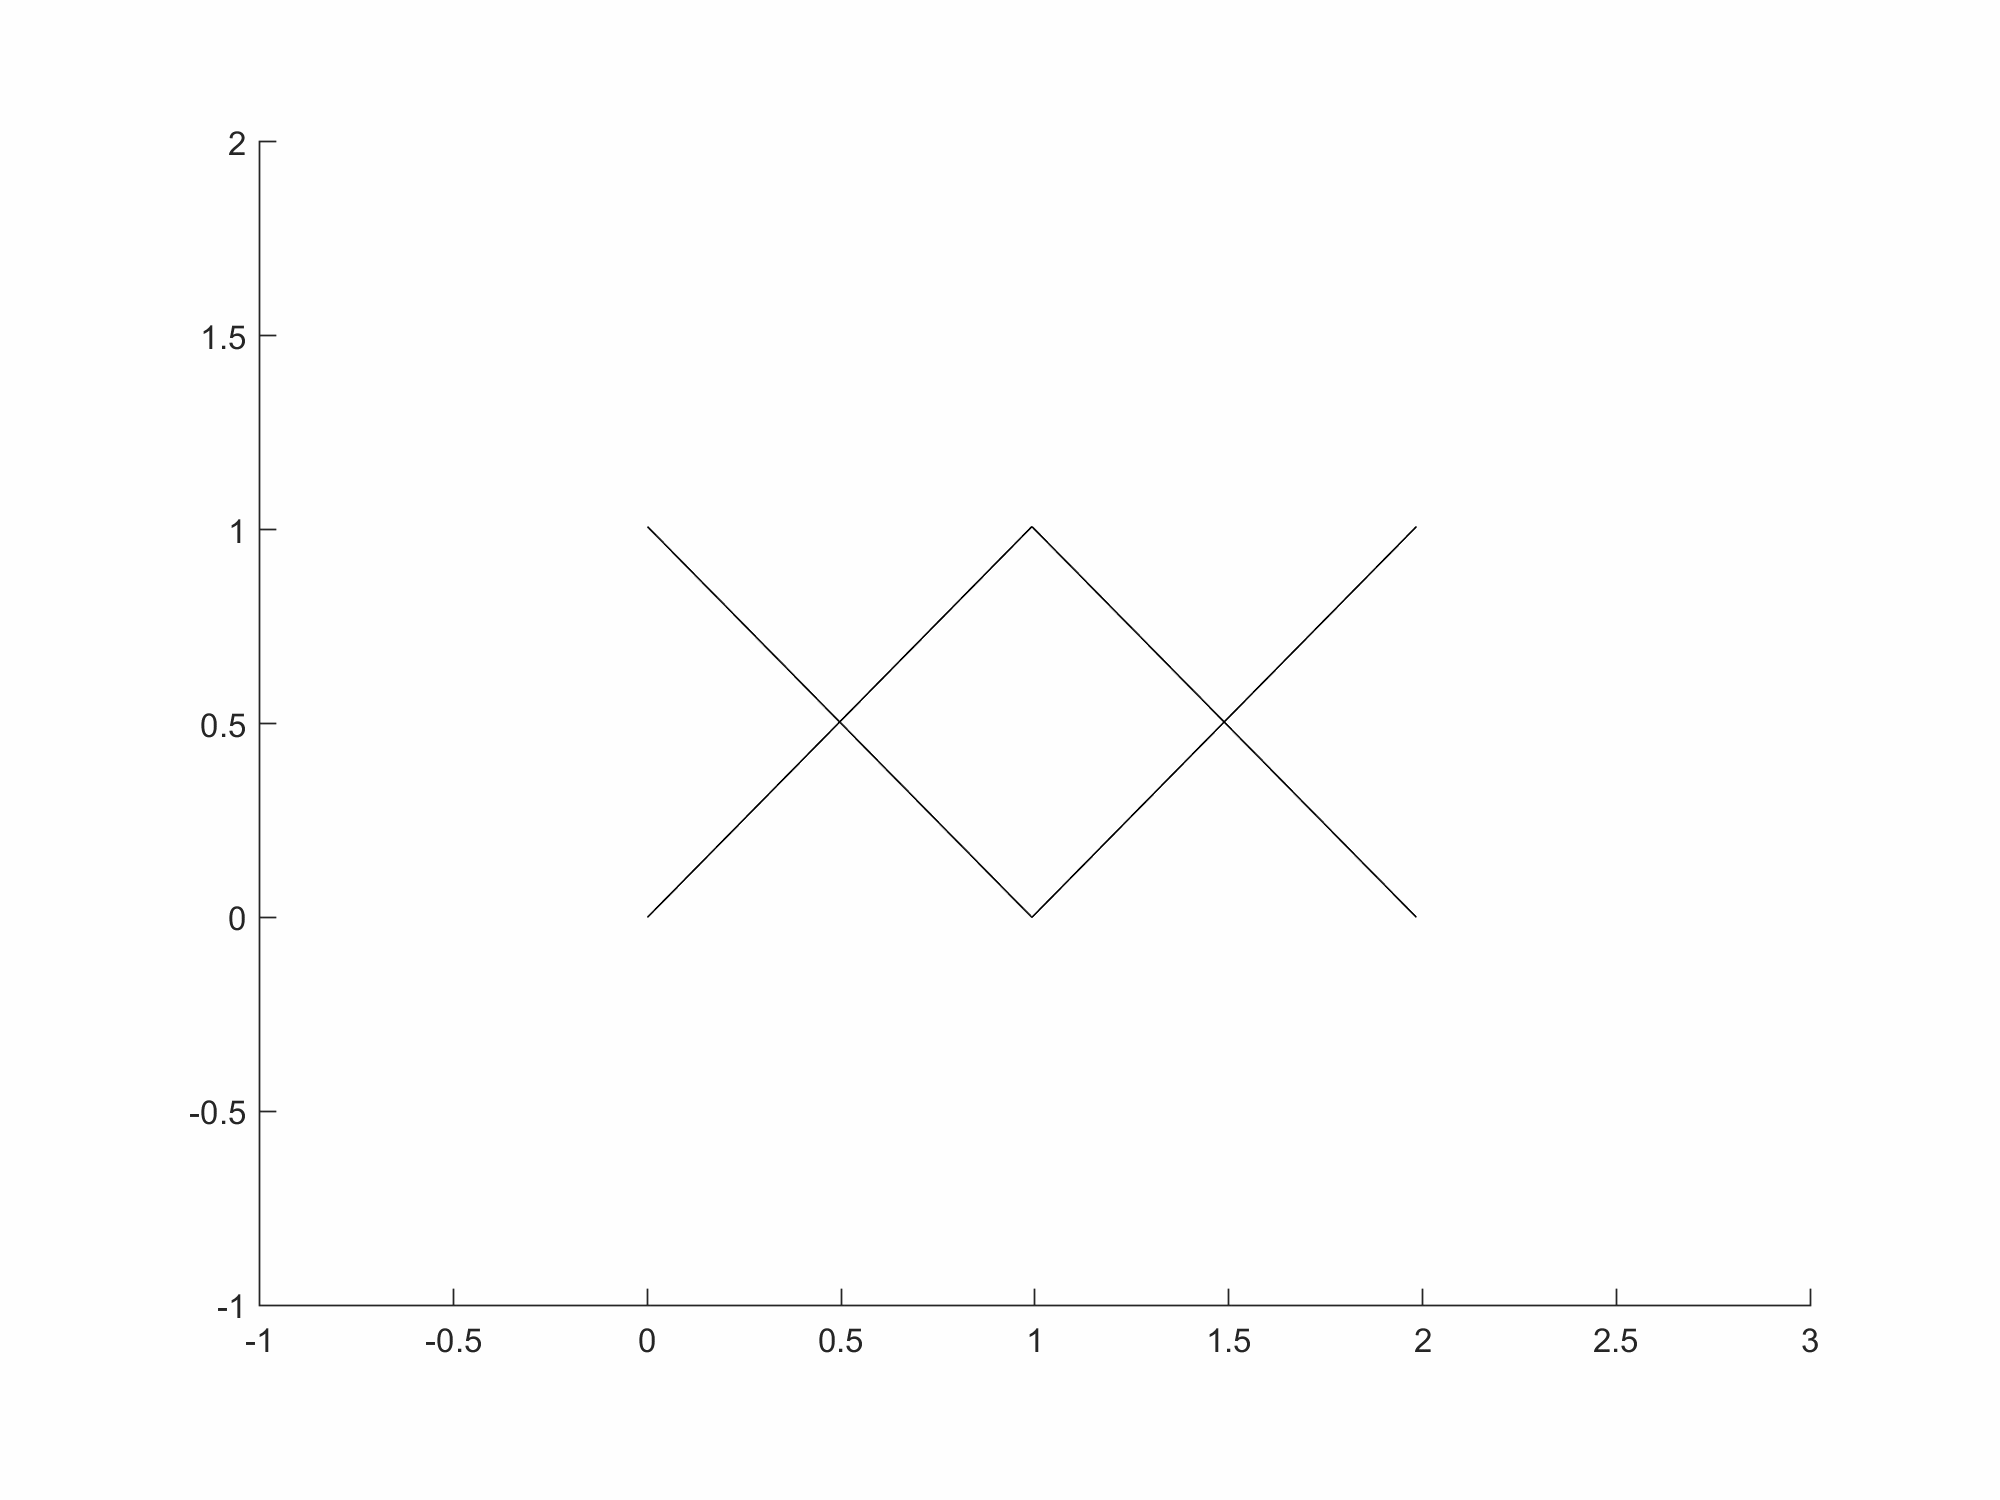

To practice, please consider working out the following problems. 

**Problem 01 **

Solve for the analytical solution and compare with the result shown in the software. How close are they? (These are simple trigonometry problems)

**Problem 02**

Add two more bays to the mechanism. Make it having four scissor systems and run the simulation.